# Solving the Fiber Length Model

A dimensionless version of the Phelps-Tucker fiber length model is implemented in `solveFLDstar`.  (FLD = fiber length distribution).  In this calculation the fiber lengths are non-dimensionalized by the unbreakable length $L_\mathrm{ub}$ and the dimensionless time is $t^* = C_B \dot{\gamma} t$, where $C_B$ is the breakage coefficient and $\dot{\gamma}$ is the scalar strain rate.  `solveFLDstar` accepts input arguments in as $\ell^* = \ell/L_\mathrm{ub}$ and $t^*$, and returns average fiber lengths as $L_n/L_\mathrm{ub}$ and $L_w/L_\mathrm{ub}$.  

Here is the calculation and a plots of $L_n$ and $L_w$ for the example in Fig. 7.4.  The remaining parameters are the length increment in the discrete FLD, $\Delta \ell = 0.2 L_\mathrm{ub}$ and the child-generation parameter, $S = 0.2$.  

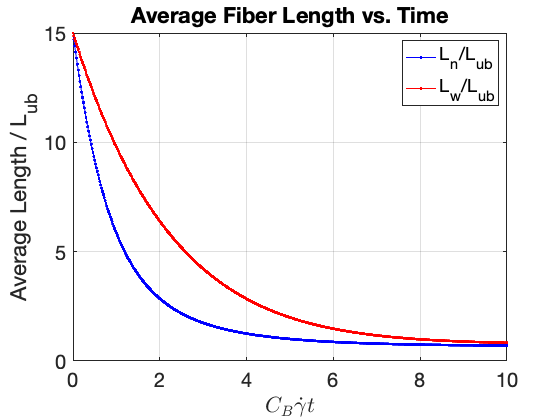

% Problem Parameters
deltaL = 0.2;        % Length increment
Lmax   = 15;         % Maximum fiber length
S      = 0.2;        % Child-distribution parameter

% Model setup
t = 0:0.02:10;       % t = 10 is close to the steady state
% Vector of dimensionless fiber lengths
Lstar = deltaL:deltaL:Lmax; 
% Initial number-based distribution: all fibers at Lmax
Nzero = zeros(size(Lstar));
Nzero(end) = 1;    

% Solve the fiber length model
[tout, N, Ln, Lw, w] = solveFLDstar(Nzero, Lstar, t, S);

% Plot the average lengths vs. time
figure
plot(t, Ln, 'b.-', t, Lw, 'r.-');
set(gca, 'FontSize', 20)
xlabel('$C_B \dot{\gamma} t$', 'Interpreter', 'LaTeX')
ylabel('Average Length / L_{ub}')
legend('L_n/L_{ub}', 'L_w/L_{ub}')
grid on
box on
title('Average Fiber Length vs. Time')

The two average lengths are initially the same, because all fibers initially have the same length.  The number-average length decreses more rapidly, as fibers are broken and shorter child fibers are generated.  Steady state is reached when all fibers are shorter than the unbreakable length.  Both $L_n$ and $L_w$ asymptote to a value slightly below $L_\mathrm{ub}$.  This is because any fiber longer than $L_\mathrm{ub}$ can still break, and some of the child fibers from those events will be shorter than $L_\mathrm{ub}$.   

The calculation also provides the full fiber length distribution at each time step.  A good way to look at that data is to plot a histogram. We use a Malab `bar` plot, since we don't need to sort values into bins.  

Plotting the weight-based distribution $w_i = w(\ell^*_i)$ is the best way to do this, since the weight-based distribution gives a better idea of the amount of fibers at each length.  

Here is code for that plot.  Change `plottime` and re-run this section to see the fiber length distribution at different times.  This code auto-scales the vertical axis, so be aware of that as you view data at different times.  

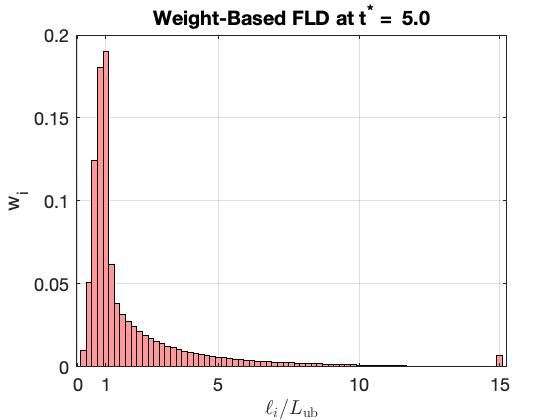

% Plot the weight-based fiber length distribution
plottime = 5;         % Dimensionless time for FLD plot
iplot = find(tout >= plottime, 1); % Index in w to plot
barcolor  = [1.0 0.6 0.6];  % Color for bars on W(L) plot
figure
bar(Lstar, w(:,iplot), 1, 'FaceColor', barcolor);
set(gca, 'FontSize', 18)
set(gca, 'Xtick', [0,1,5,10,15])  % Tick mark at L/Lub = 1
xlabel('$\ell_i / L_\mathrm{ub}$', 'Interpreter', 'LaTeX');
ylabel('w_i')
grid on
box on
title(sprintf('Weight-Based FLD at t^* = %4.1f', tout(iplot)))

At $t^* = 5$ there has been a great deal of breakage, but a small amount of fibers at the initial length is still present.  Try $t^* = 1.5$ to see a very early stage of change from the uniform initial length to a more typical FLD.  By $t^* = 7$ there are almost no fibers with the initial length, and a strong peak around $L_\mathrm{ub}$ has developed.   